% Create a new fuzzy inference system
fuzzy = mamfis('Name', 'WateringSystem');

% Define fuzzy sets for temperature
fuzzy = addInput(fuzzy, [-10 50],'Name','Temperature');
fuzzy = addMF(fuzzy, 'Temperature', 'trapmf', [-10 0 10 13], 'Name', 'Cold');
fuzzy = addMF(fuzzy, 'Temperature', 'trapmf', [10 20 20 30], 'Name', 'Medium');
fuzzy = addMF(fuzzy, 'Temperature', 'trapmf', [20 30 40 50],'Name','Hot');

% Define fuzzy sets for humidity
fuzzy = addInput(fuzzy, [0 80],'Name','Humidity');
fuzzy = addMF(fuzzy, 'Humidity', 'trapmf',[0 10 20 30],'Name','Low');
fuzzy = addMF(fuzzy, 'Humidity', 'trapmf',[20 40 50 60],'Name','Medium');
fuzzy = addMF(fuzzy, 'Humidity', 'trapmf',[50 60 70 80],'Name','High');

% Define fuzzy sets for moisture
fuzzy = addInput(fuzzy, [0 400],'Name','Moisture');
fuzzy = addMF(fuzzy, 'Moisture', 'trapmf',[0 220 270 300],'Name','Wet');
fuzzy = addMF(fuzzy, 'Moisture', 'trapmf',[270 280 310 320],'Name','Medium');
fuzzy = addMF(fuzzy, 'Moisture', 'trapmf',[310 320 390 400],'Name','Dry');

% Define fuzzy sets for light
fuzzy = addInput(fuzzy, [0 7],'Name','Light');
fuzzy = addMF(fuzzy, 'Light', 'trapmf',[0 1 2 3],'Name','Low');
fuzzy = addMF(fuzzy, 'Light', 'trapmf',[2 3 4 5],'Name','Medium');
fuzzy = addMF(fuzzy, 'Light', 'trapmf',[4 5 6 7],'Name','High');

% Define the watering radius and maximum volume
radie = 11 * 0.5; % cm
volumeWater = radie * radie * 2.5 * pi % Volume per week

volumeWater = 237.5829

volumeWaterPerDay = volumeWater / 7;
numberSamplesPerDay = 5;%(24 * 60) / 20;
mlPerWatering = volumeWaterPerDay / numberSamplesPerDay

mlPerWatering = 6.7881

wateringMax = volumeWaterPerDay;

% Define fuzzy sets for watering levels
fuzzy = addOutput(fuzzy,[0 wateringMax],'Name','Watering');
fuzzy = addMF(fuzzy, 'Watering', 'trapmf', [0 0 wateringMax*0.05 wateringMax*0.1], 'Name', 'None');
fuzzy = addMF(fuzzy, 'Watering', 'trapmf', [wateringMax*0.05 wateringMax*0.15 wateringMax*0.2 wateringMax*0.5], 'Name', 'Low');
fuzzy = addMF(fuzzy, 'Watering', 'trapmf', [wateringMax*0.25 wateringMax*0.3 wateringMax*0.4 wateringMax*0.6], 'Name', 'Medium');
fuzzy = addMF(fuzzy, 'Watering', 'trapmf', [wateringMax*0.4 wateringMax*0.6 wateringMax*0.8 wateringMax*1.0], 'Name', 'High');
% Define fuzzy rules
rules = [
    "Temperature==Cold & Humidity==Low & Moisture==Dry & Light==Low => Watering=High"
    "Temperature==Cold & Humidity==Low & Moisture==Dry & Light==Medium => Watering=High"
    "Temperature==Cold & Humidity==Low & Moisture==Dry & Light==High => Watering=Medium"
    "Temperature==Cold & Humidity==Medium & Moisture==Dry & Light==Low => Watering=High"
    "Temperature==Cold & Humidity==Medium & Moisture==Dry & Light==Medium => Watering=High"
    "Temperature==Cold & Humidity==Medium & Moisture==Dry & Light==High => Watering=Medium"
    "Temperature==Cold & Humidity==High & Moisture==Dry & Light==Low => Watering=High"
    "Temperature==Cold & Humidity==High & Moisture==Dry & Light==Medium => Watering=High"
    "Temperature==Cold & Humidity==High & Moisture==Dry & Light==High => Watering=Medium"
    "Temperature==Medium & Humidity==Low & Moisture==Dry & Light==Low => Watering=High"
    "Temperature==Medium & Humidity==Low & Moisture==Dry & Light==Medium => Watering=High"
    "Temperature==Medium & Humidity==Low & Moisture==Dry & Light==High => Watering=Medium"
    "Temperature==Medium & Humidity==Medium & Moisture==Dry & Light==Low => Watering=High"
    "Temperature==Medium & Humidity==Medium & Moisture==Dry & Light==Medium => Watering=High"
    "Temperature==Medium & Humidity==Medium & Moisture==Dry & Light==High => Watering=Medium"
    "Temperature==Medium & Humidity==High & Moisture==Dry & Light==Low => Watering=High"
    "Temperature==Medium & Humidity==High & Moisture==Dry & Light==Medium => Watering=High"
    "Temperature==Medium & Humidity==High & Moisture==Dry & Light==High => Watering=Medium"
    "Temperature==Hot & Humidity==Low & Moisture==Dry & Light==Low => Watering=High"
    "Temperature==Hot & Humidity==Medium & Moisture==Dry & Light==Low => Watering=High"
    "Temperature==Hot & Humidity==Medium & Moisture==Dry & Light==Medium => Watering=Medium"
    "Temperature==Hot & Humidity==Medium & Moisture==Dry & Light==High => Watering=Medium"
    "Temperature==Hot & Humidity==High & Moisture==Dry & Light==Low => Watering=Medium"
    "Temperature==Hot & Humidity==High & Moisture==Dry & Light==Medium => Watering=Medium"
    "Temperature==Hot & Humidity==High & Moisture==Dry & Light==High => Watering=Low"
];

fuzzy = addRule(fuzzy, rules);

inputValues = [0, 0, 0, 1]; % Example input values for Temperature, Humidity, Moisture, and Light
output = evalfis(fuzzy, inputValues);


disp('Watering amount:');

Watering amount:


disp(output);

   16.9702



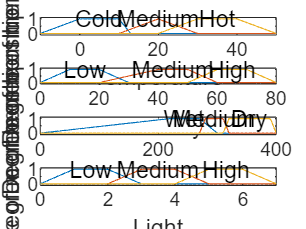


figure;
title('Input Fuzzy Sets');
subplot(4, 1, 1);
plotmf(fuzzy, 'input', 1);
subplot(4, 1, 2);
plotmf(fuzzy, 'input', 2);
subplot(4, 1, 3);
plotmf(fuzzy, 'input', 3);
subplot(4, 1, 4);
plotmf(fuzzy, 'input', 4);

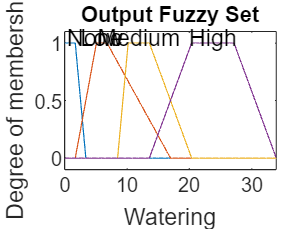


figure;
plotmf(fuzzy, 'output', 1);
title('Output Fuzzy Set');